# ThingSpeak Dashboard for Live RUL Estimation of a Servo Motor Gear Train

This example shows how to setup a ThingSpeak™ dashboard to estimate and visualize the Remaining Useful Life (RUL) of a servo motor gear train. A ThingSpeak dashboard consists of a ThingSpeak channel set up with **relevant data streams** and **MATLAB analysis scripts**. The **MATLAB scripts run real-time** in ThingSpeak.

For this example, a set of synthetic motor current signal data is generated that is used to visualize and predict the RUL of the gear train inside the servo. Motor current signature analysis (MCSA) of the current signal driving a hobby servo motor is used to extract frequency-domain (spectral) features from several frequency regions of interest indicative of motor and gear train faults. A single feature or a combination of features are used construct a Health Indicator (HI) for subsequent RUL estimation. MCSA is a useful method for the diagnosis of faults that induce torque or speed fluctuations in the servo gear train, which in turn result in correlated motor current changes. MCSA has been proven to be ideal for motor fault analysis as only the motor current signal is required for analysis, which eliminates the need for additional and expensive sensing hardware. Gear fault detection using traditional vibration sensors is challenging, especially in cases where the gear train is not easily accessible for instrumentation with accelerometers or other vibration sensors.

For more information about the data stream and hardware setup, see [Motor Current Signature Analysis for Gear Train Fault Detection](docid:predmaint_ug#mw_38703a57-69d6-408a-9bd0-adbaf306b80d) and [Live RUL Estimation of a Servo Gear Train using ThingSpeak](docid:predmaint_ug#mw_d56b89a3-b2b1-4c73-84cc-c7ed92b4fa33).

The simplified workflow to estimate and display the RUL of the servo motor gear train includes the following steps:

- Set up ThingSpeak dashboard

- ***Periodically*** generate servo gear train features 

- Estimate the RUL as the features are generated

- Setup RUL alert in ThingSpeak

## Dashboard Setup

The first step of creating a dashboard is to setup a ThingSpeak channel with the appropriate channel IDs to stream, analyze and display the data. You can then create relevant MATLAB Analysis scripts as described in the successive sections in this example. For more information on setting up a ThingSpeak channel and to stream your data, see [Configure Accounts and Channels](https://www.mathworks.com/help/thingspeak/users.html) and [Live RUL Estimation of a Servo Gear Train using ThingSpeak](docid:predmaint_ug#mw_d56b89a3-b2b1-4c73-84cc-c7ed92b4fa33).

For this example, channel 1558487 was created to run, analyze and display the RUL of the synthetic servo motor data. Run the following command to access this dashboard.

web('https://thingspeak.com/channels/1558487')

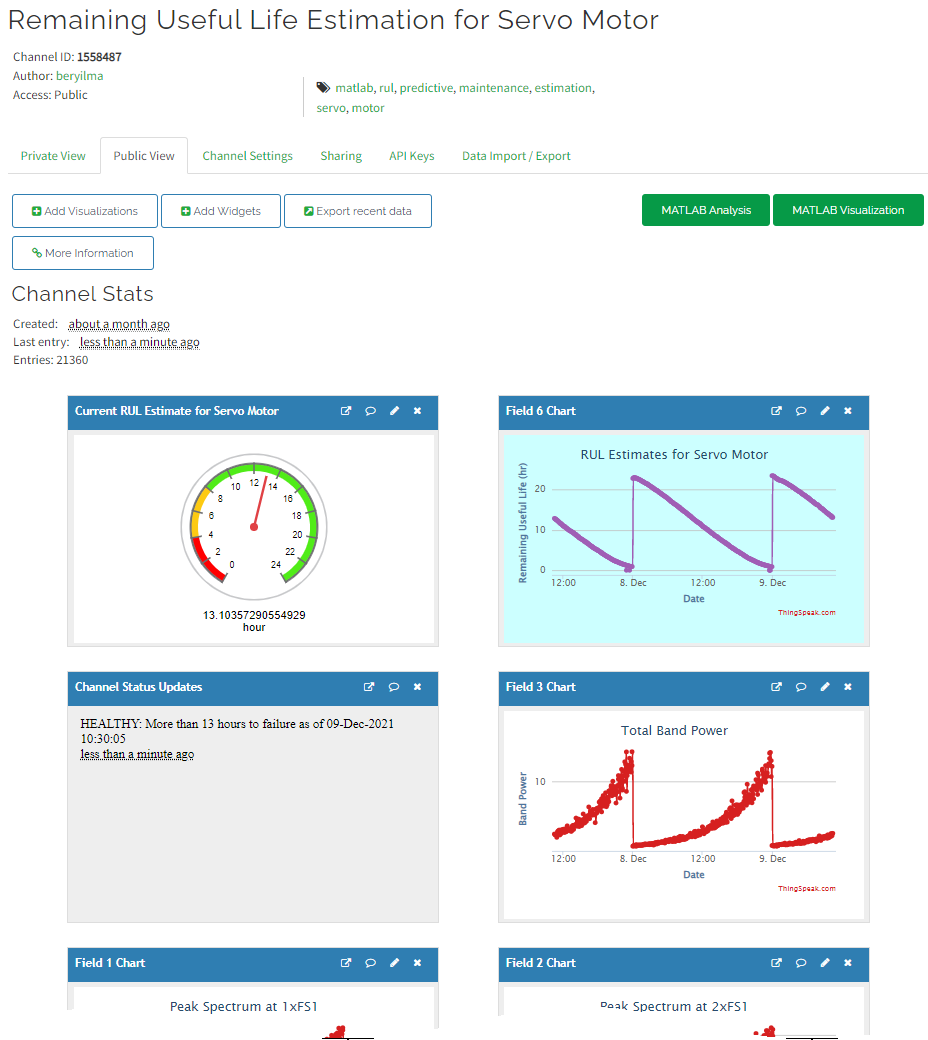

ThingSpeak Dashboard - Remaining Useful Life Estimation

Since this example requires the model state to be stored between evaluations, change the `Metadata` setting of the channel based on the RUL model for this example. You normally do not need to change the `Metadata` setting when setting up your own ThingSpeak channel.

For this example, assume that an `ExponentialDegradationModel` was trained with historical data using the `fit` command. The `fit` command estimates a prior for the model's parameters based on the historical records in training data. The `Prior` property of the trained model contains the estimated model parameters `Theta`, `Beta`, `Rho`, etc. For details of these model parameters, see [exponentialDegradationModel](docid:predmaint_ref#mw_23613be5-c05a-4f1e-ac73-6cbe03911a9a).

Extract the model's prior from the fitted exponential degradation model and add any fixed parameters (e.g., Phi) as part of the state structure. See the example [Update RUL Prediction as Data Arrives](docid:predmaint_ug#mw_224b54ac-b4d8-4afd-8660-93e89f67fb00) for using the fit method to initialize model parameters from training (historical) data.

For this example, assume that the model parameter priors are set as follows:

Convert the state structure to a string representation so that you can manually copy it to the channel's `Metadata` setting.

Manually save the resulting model state string into the `Metadata` setting of the channel:

## Generate Synthetic Servo Motor Features

For this example, the next step is to generate synthetic servo motor features and save the values to the ThingSpeak channel as separate fields. For your use case, you can use feature values from a Cloud source or compute them from real-time hardware streaming data.

The synthetic motor signal data being generated in this example utilizes the servo motor and gear train specifications listed below. The servo consists of four pairs of meshing nylon gears as illustrated in the figure below. The pinion P1 on the DC motor shaft meshes with the stepped gear G1. The pinion P2 is a molded part of the stepped gear G1 and meshes with the stepped gear G2. The pinion P3, which is a molded part of gear G2, meshes with the stepped gear G3. Pinion P4, which is molded with G3, meshes with the final gear G4 that is attached to the output shaft. The stepped gear sets G1 and P2, G2 and P3, and G3 and P4 are free spinning gears − that is, they are not fixed to their respective shafts. The set of gears provides a 278:1 reduction going from a motor speed of about 6117 rpm to about 22 rpm at the output shaft when the DC motor is driven at 5 volts.

For more information about the hardware model, see [Live RUL Estimation of a Servo Gear Train using ThingSpeak](docid:predmaint_ug#mw_d56b89a3-b2b1-4c73-84cc-c7ed92b4fa33).

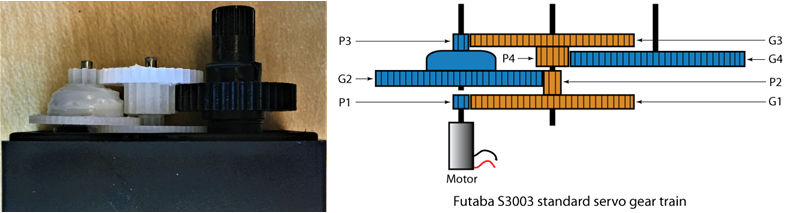

The following table outlines the tooth count and theoretical values of output speed, gear mesh frequencies, and cumulative gear reduction at each gear mesh.

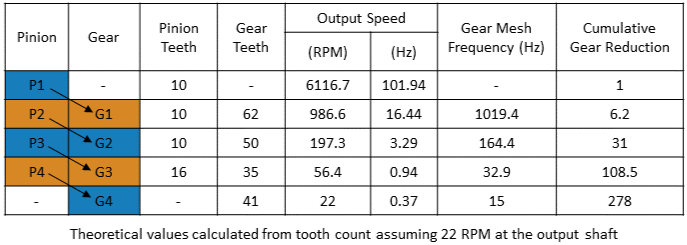

The ThingSpeak dashboard for this example uses the following three MATLAB Analysis scripts:

- **Generate Synthetic Servo Motor Features**

- **Calculate Remaining Useful Life Estimate**

- **Send RUL Alert**

You can use the MATLAB Analysis App to explore and analyze the data stored in your ThingSpeak channel. For more information, see [MATLAB Analysis App](https://www.mathworks.com/help/thingspeak/matlab-analysis-app.html).

You can find the above MATLAB scripts associated with channel 1558487 in the current directory of this example.

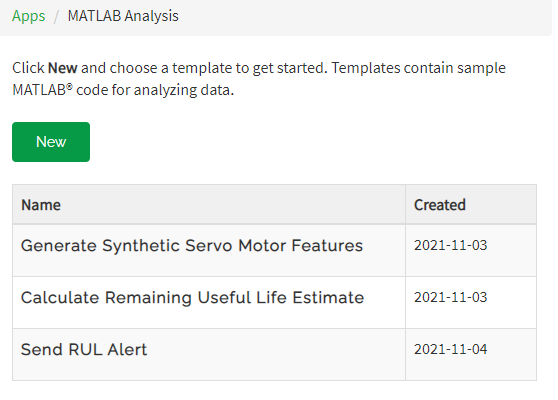

The following [MATLAB Analysis](https://www.mathworks.com/help/thingspeak/matlab-analysis-app.html) code is associated with the **Generate Synthetic Servo Motor Features** script. Use [TimeControl](https://www.mathworks.com/help/thingspeak/timecontrol-app.html) to run the script every 5 minutes to trigger the computation of new servo motor features from available or synthetic data. The **Generate Synthetic Servo Motor Features** script is associated with a **TimeControl** configured as follows:

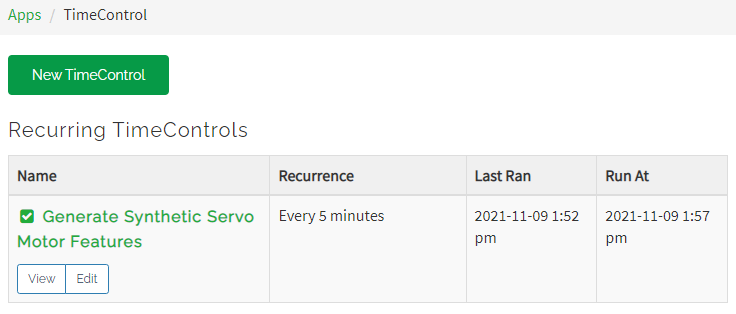

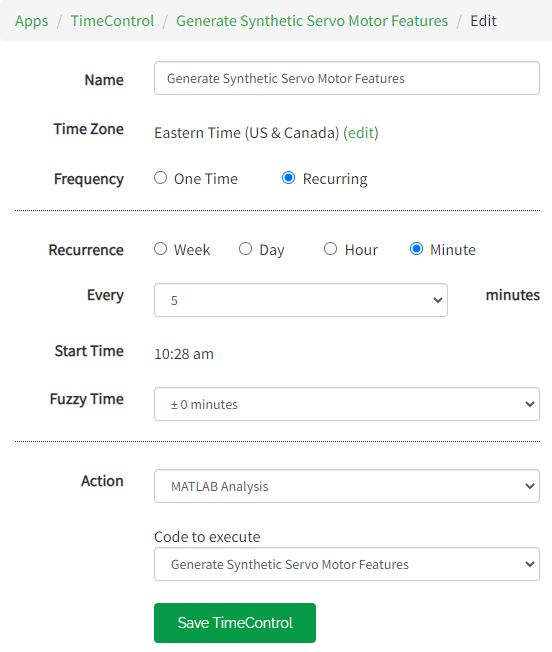

The contents of the **Generate Synthetic Servo Motor Features** script are as follows:

**Simulate time-domain motor features**

For the servo motor used in the example, the motor winding current fluctuates between `308` mA  and `320` mA, and the speed fluctuates between `20` rpm and `23` rpm.

**Simulate frequency domain features of the motor current**

The power spectrum amplitudes at motor shaft frequencies (1xFS1 and 2xFS1) and the total band power are simulated as follows:

Input the parameters to simulate complete degradation of the servo motor over the course of a full day.

Peak power spectrum amplitude at the first harmonic of the motor shaft frequency (1xFS1) changes linearly between -30 dB and 10 dB as degradation increases. Add white noise to simulate more realistic sensor data. For more information about the frequencies, see [Live RUL Estimation of a Servo Gear Train using ThingSpeak](docid:predmaint_ug#mw_d56b89a3-b2b1-4c73-84cc-c7ed92b4fa33).

Peak power spectrum amplitude at the second harmonic of the motor shaft frequency (2xFS1) changes linearly between -20 dB and 0 dB as degradation increases. Add white noise to simulate more realistic sensor data.

Total band power of the motor current changes exponentially between 1 and 13 as degradation increases and failure is assumed to occur at the threshold value 13. Add white noise to simulate more realistic sensor data. Use the band power as the health index for RUL estimations.

**Configure the Channel ID and the Write API Key values**

Replace the [] with channel ID to write data to your ThingSpeak dashboard:

Enter the `Write API Key` between the quotes:

Write the features to the channel specified by the `writeChannelID` variable.

The features will be displayed in the fields 1-5 of your ThingSpeak channel:

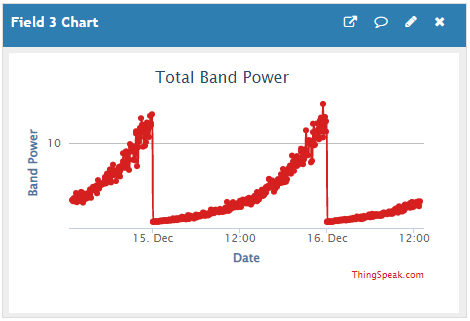`

Total Band Power Chart

## Calculate Remaining Useful Life Estimate

Next, setup a [MATLAB Analysis](https://www.mathworks.com/help/thingspeak/matlab-analysis-app.html) script that calculates the remaining useful life of the servo motor using the total band power of the motor current as the health indicator. The script also saves the RUL estimate to the ThingSpeak channel in the field **Remaining Useful Life (hr)**.

The following [MATLAB Analysis](https://www.mathworks.com/help/thingspeak/matlab-analysis-app.html) code is associated with the **Calculate Remaining Useful Life Estimate **script. Use the [React](https://www.mathworks.com/help/thingspeak/react-app.html) control that runs whenever a new, valid feature value is added to the **Total Band Power** field of your channel.

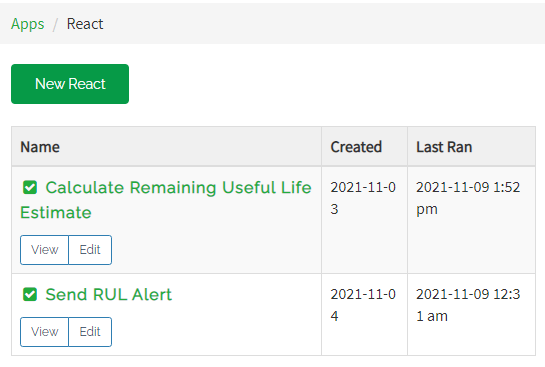

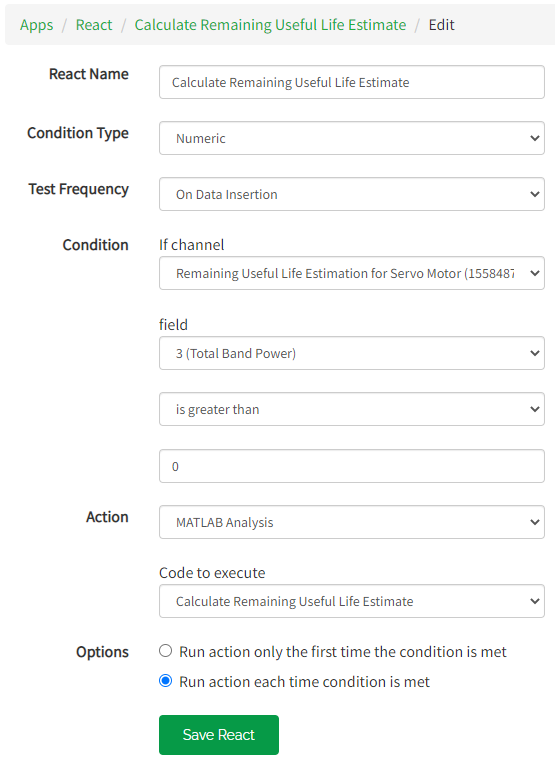

**Configure the channel ID and then read the API key values**

Replace the [] with channel ID to read data from your ThingSpeak channel.

If your channel is private, then enter the **Read API Key** between the quotes.

For this example, the **Total Band Power** feature is stored in field 3 of the channel.

**Read the data since the last servo motor replacement**

For the example, we assume that the servo motor fails and is replaced every 24 hours at 12:00 AM.

Read feature data and remove any invalid or empty values.

Return if there is no valid data available, for example, right after the servo motor was replaced.

**Construct the exponential degradation model**

Use the **Total Band Power** as the health index and compute the current RUL estimate of the servo motor. Reload from channel **Metadata** setting the initial state of the model parameters obtained from fitting historical data to the degradation model. Use the prior parameters to initialize the degradation model before estimating a new RUL value from available data.

Set RUL degradation threshold for the health index (Total Band Power).

The data here is not historical data, but rather recent real-time observations of the servo motor features recorded in the fields of the ThingSpeak channel.

Update the degradation model using available feature values since the servo motor was last replaced. Then, compute the current RUL estimate based on the failure threshold.

**Configure the Channel ID and the Write API Key values**

Replace the [] with channel ID to write data to your ThingSpeak channel.

Enter the **Write API Key** between the quotes.

Write the updated RUL estimate to the channel specified by the `writeChannelID` variable. For this example, the RUL estimate value is stored in field 6 of the ThingSpeak channel.

Field 6 of the channel tracks the RUL estimates for the servo motor:

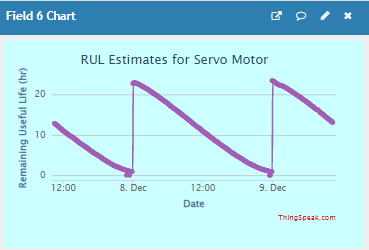

RUL Estimate Chart

Add a **Field Value Gauge** widget to display the current RUL estimate. For more information, see [Channel Display Widgets](https://www.mathworks.com/help/thingspeak/channel_display_widgets.html).

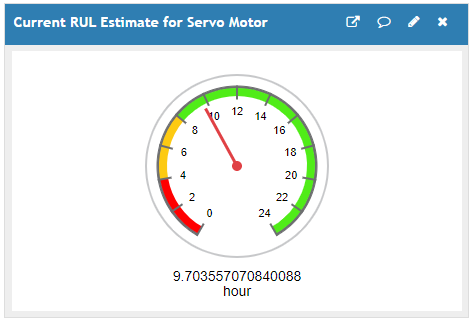

RUL Estimate Gauge

## Send RUL Alert

You can also setup a [MATLAB Analysis](https://www.mathworks.com/help/thingspeak/matlab-analysis-app.html) script to send an RUL status alert to the channel about the impending servo failure.

The following [MATLAB Analysis](https://www.mathworks.com/help/thingspeak/matlab-analysis-app.html) code is associated with the **Send RUL Alert** script. Use [React](https://www.mathworks.com/help/thingspeak/react-app.html) control to send a text message alert (as a status update in the channel) every 10 minutes while the current RUL estimate for an impending failure is determined to be less than 4 hours. If the RUL estimate is less than 8 hours, a warning message is displayed.

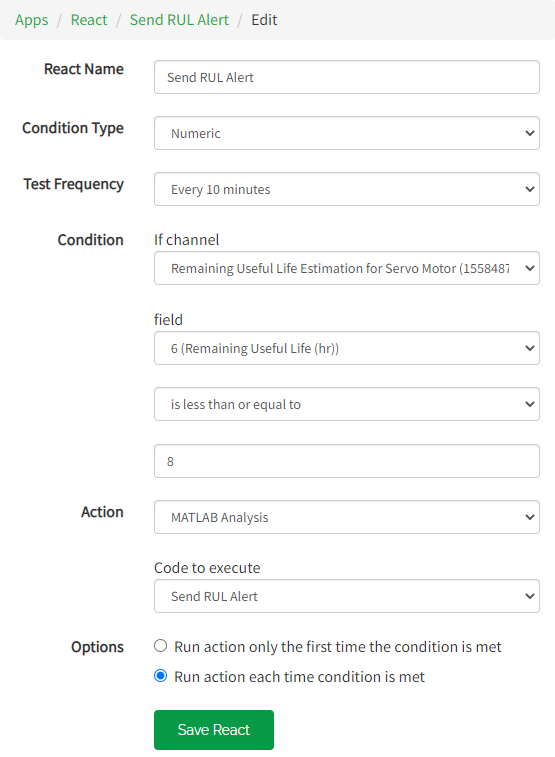

**Configure the Channel ID value**

Replace the [] with channel ID to read data from your ThingSpeak channel.

In this example, the RUL estimate is stored in field 6 of the channel.

Read recent RUL estimates and remove any invalid or empty values.

**Configure the Write API Key value**

Enter the **Write API Key** value between the quotes:

Post status update message to your ThingSpeak channel.

Any alerts for a pending failure are shown in the **Channel Status Updates** view:

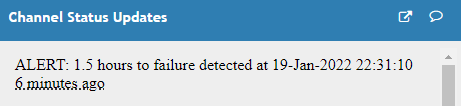

Channel Status Update Window

This functionality can be replaced with code to send text messages, emails, or Twitter updates instead. For more information, see [ThingTweet App](https://www.mathworks.com/help/thingspeak/thingtweet-app.html) and [ThingHTTP App](https://www.mathworks.com/help/thingspeak/thinghttp-app.html).

Alternatively, use the following code to send an email alert. For more information and an example, see [Alerts API](https://www.mathworks.com/help/thingspeak/alerts-api.html) and [Analyze Channel Data to Send Email Notification.](https://www.mathworks.com/help/thingspeak/analyze-channel-data-to-send-email.html)

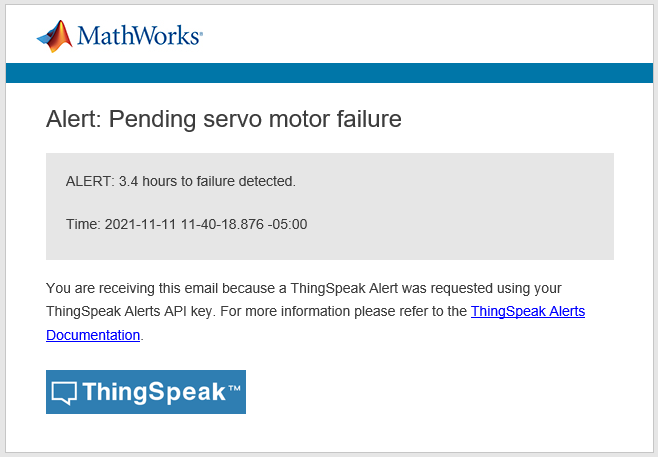

Email Alert Message

## Supporting Functions

The `loadModelState` function loads the model state (i.e., the prior for the model parameters) from the **Metadata** setting of the channel and converts it to a MATLAB variable (struct). You can access the following MATLAB scripts in the working directory of this example.

The `sendALertEmail` function sends an alert email indicating the estimated RUL value.

*Copyright 2021 The MathWorks, Inc.*